**State Space Modeling Tutorial - Part 1, 1D Linear Gaussian Model**

In this tutorial, we will explore a few simple examples of state-space models, and estimation and inference for these models. The goal is to develop some intuition for how these models work. 

We start by generating data from a one-dimensional linear, Gaussian state model and a one-dimensional linear, Gaussian observation model.

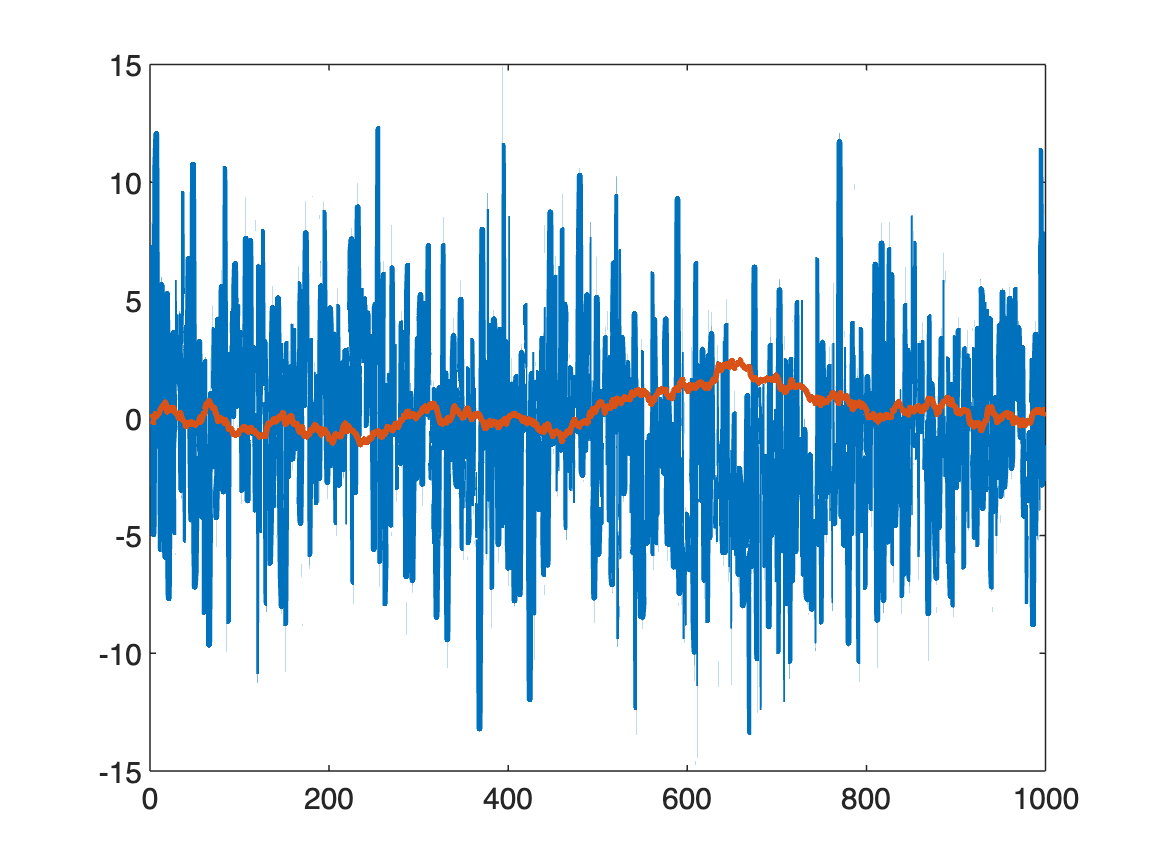

%% Generate Data
% State model: x(t) = A*x(t-1) + Sigx * N(0,1)
% Observation model: y(t) = H*x(t) + Sigy * N(0,1)

rng(0); set(0,'DefaultLineMarkerSize',10); set(0,'DefaultLineLineWidth',2);
A = .99; H = -2; Sigx = .1; Sigy = 4;

N = 1000; x = zeros(1,N); y = zeros(1,N); dN = zeros(1,N);
for i = 2:N
    x(i) = A*x(i-1)+Sigx*normrnd(0,1);
    y(i) = H*x(i)+Sigy*normrnd(0,1);
end

plot(1:N,y,1:N,x);

The state x(t) is shown in red and the noisy observations y(t) are shown in blue.

If we were unaware of the state model, we could still try to estimate each x(t) value, based on the corresponding y(t) value. 

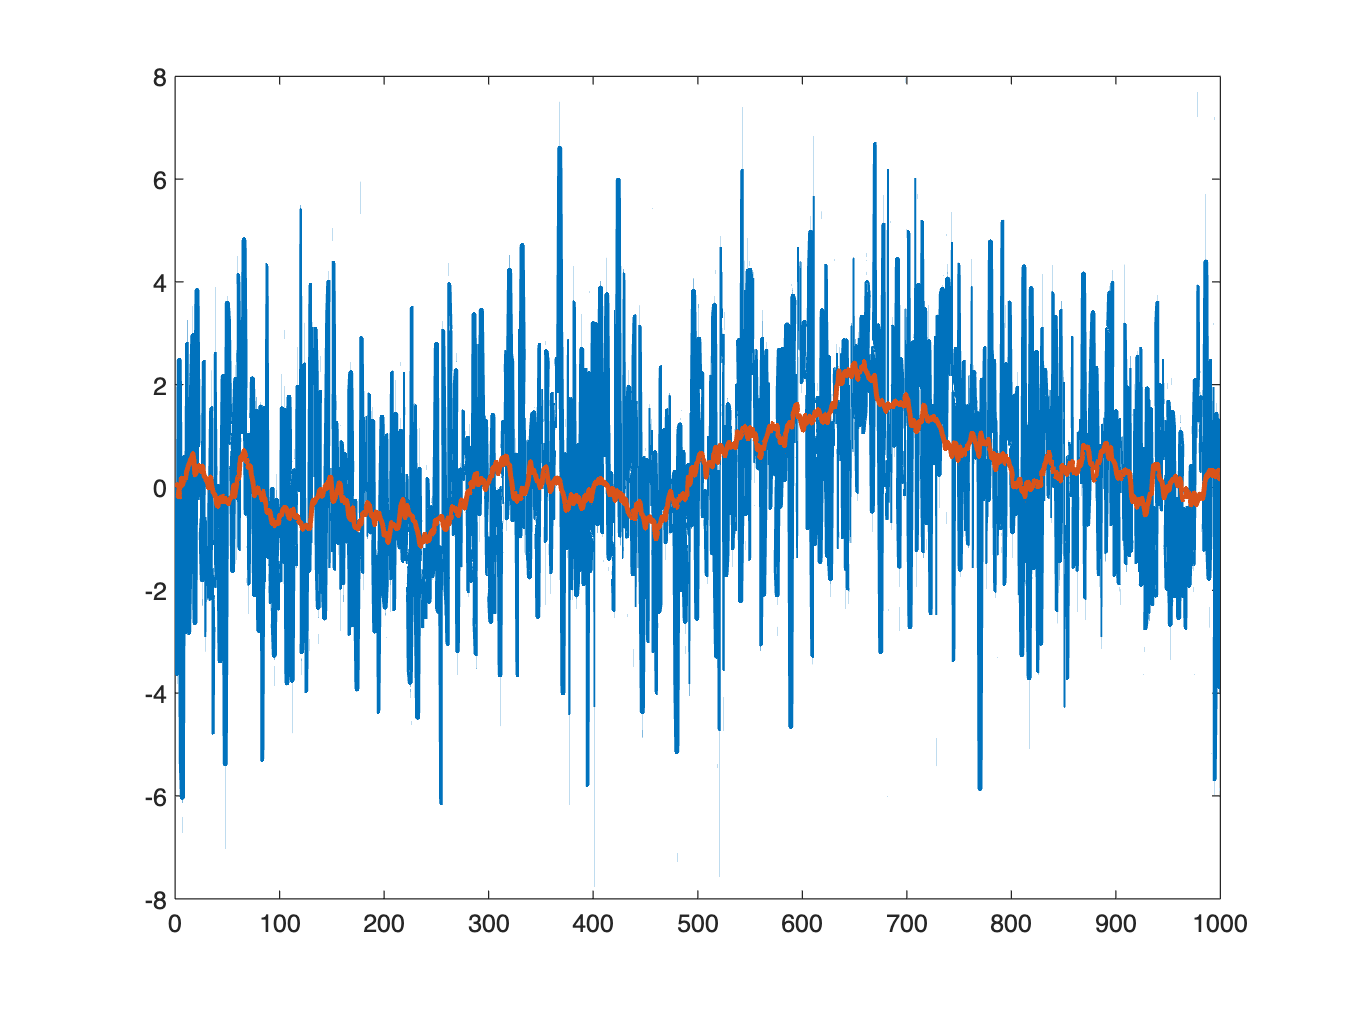

%% ML estimate (ignoring latent model)
xhatML = inv(H)*y;          % xhatML(t) = E[x(t)|y(t)] 
plot(1:N,xhatML,1:N,x);

The true value of the state x(t) is shown in red and the estimated state ${\hat{x} }_{\textrm{ML}} \left(t\right)$ is shown in blue.

Notice that the estimates, like the observations, are very noisy. This is not surprising, since each estimate is based on a single observed data point.

Now, we will use our knowledge of the dynamics of the state process to estimate the state in a way that combines information from all the observations up to the current time. This is called filtering. Mathematically, the filter problem is to compute the probability distribution,$p\left(x_t |y_{1:t} \right)$. In class, we showed that this distribution can be expressed iteratively as a function of its value at a previous time step based on Bayes rule: $p\left(x_t |y_{1:t} \right)=p\left(y_t |x_t \right)\int p\left(x_t |x_{t-1} \right)p\left(x_{t-1} |y_{1:t-1} \right)dx_t$. 

We can compute this integration numerically as a Riemann sum. In the code below, we construct a matrix, OST, that contains $p\left(x_t |x_{t-1} \right)$ for each value of $x_t$ and $x_{t-1}$, and multiply it by a vector representing $p\left(x_{t-1} |y_{1:t-1} \right)$ for each value of $x_{t-1}$.

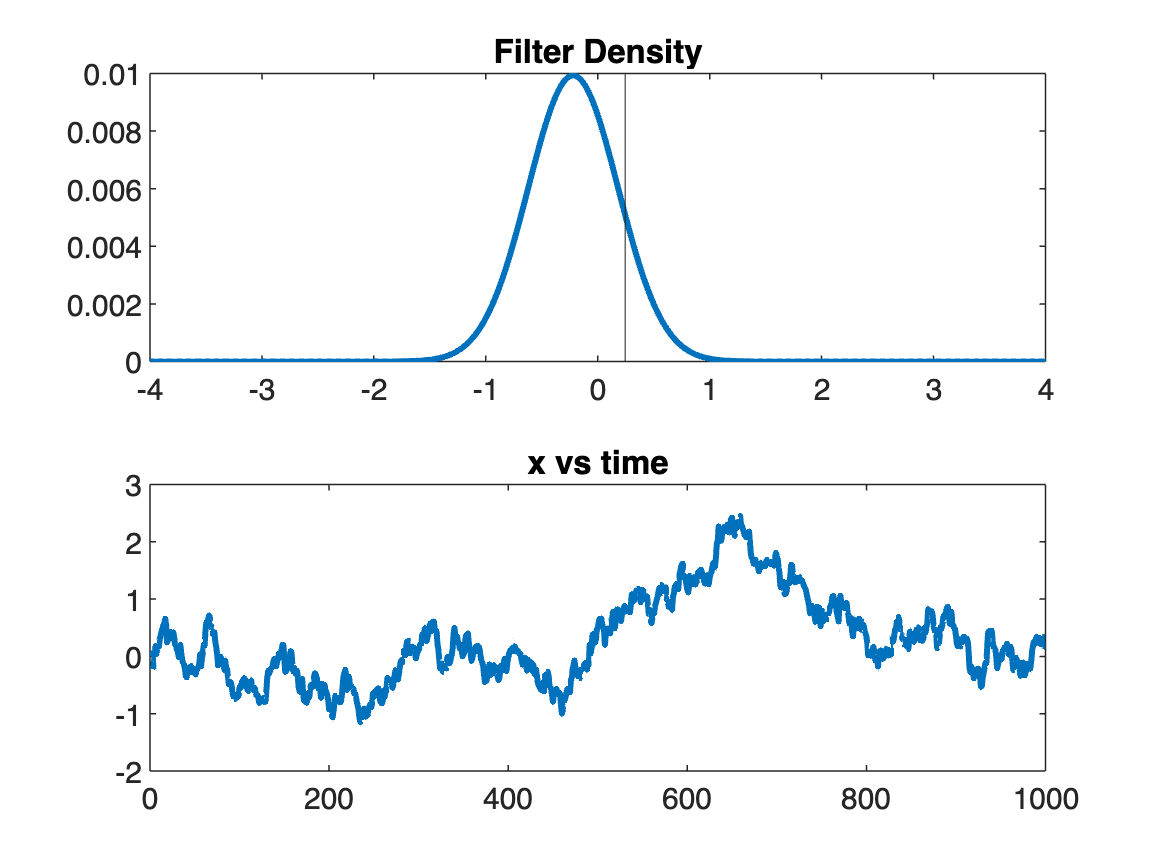

%% Filter Solution (Numerical integration)
xs = [-4:.01:4]'; xhatN = zeros(length(xs),N);                  % xs = grid of x values; allocate memory for xhatN = p(x(t)|y(1:t))
xhatN(:,1) = normpdf(xs,0,1)/sum(normpdf(xs,0,1));              % Initial distribution p(x(1))
OST = normpdf(ones(size(xs))*A*xs',xs*ones(size(xs')),Sigx);    % One-step transition matrix
for i = 2:N,

    post = OST*xhatN(:,i-1) .* normpdf(y(i),H*xs,Sigy);         % Compute unnormalized density p(x(t)|y(1:t))
    xhatN(:,i)=post./sum(post);                                 % Normalize to compute xhatN = p(x(t)|y(1:t))
    
    subplot(211); plot(xs,xhatN(:,i)); xline(x(i)); ylim([0 .01]); title('Filter Density');
    subplot(212); plot(1:N,x); xline(i); title('x vs time');
    drawnow;
end;

This code should generate a movie that shows in the top panel the filter density, $p\left(x_t |y_{1:t} \right)$, at each time step. The vertical line show the actual value of x(t). The bottom plot shows the true values of x(t) through time with a vertical line that indicates the time step, t.

Another way to compute the integral above is with a particle filter (also known as a sequential Monte Carlo or SMC method). Here. we generate a large set of samples of state values and allow each one to evolve independently according the the state-model dynamics. We then assign a weight to each sample based on the likelihood of observing the current data point based on the sample's state value. Finally, we resample the samples randomly based on their weights, so that samples that make the data most likely tend to be resampled many times, while samples that make the data unlikely tend not to be resampled and drop out of the set. 

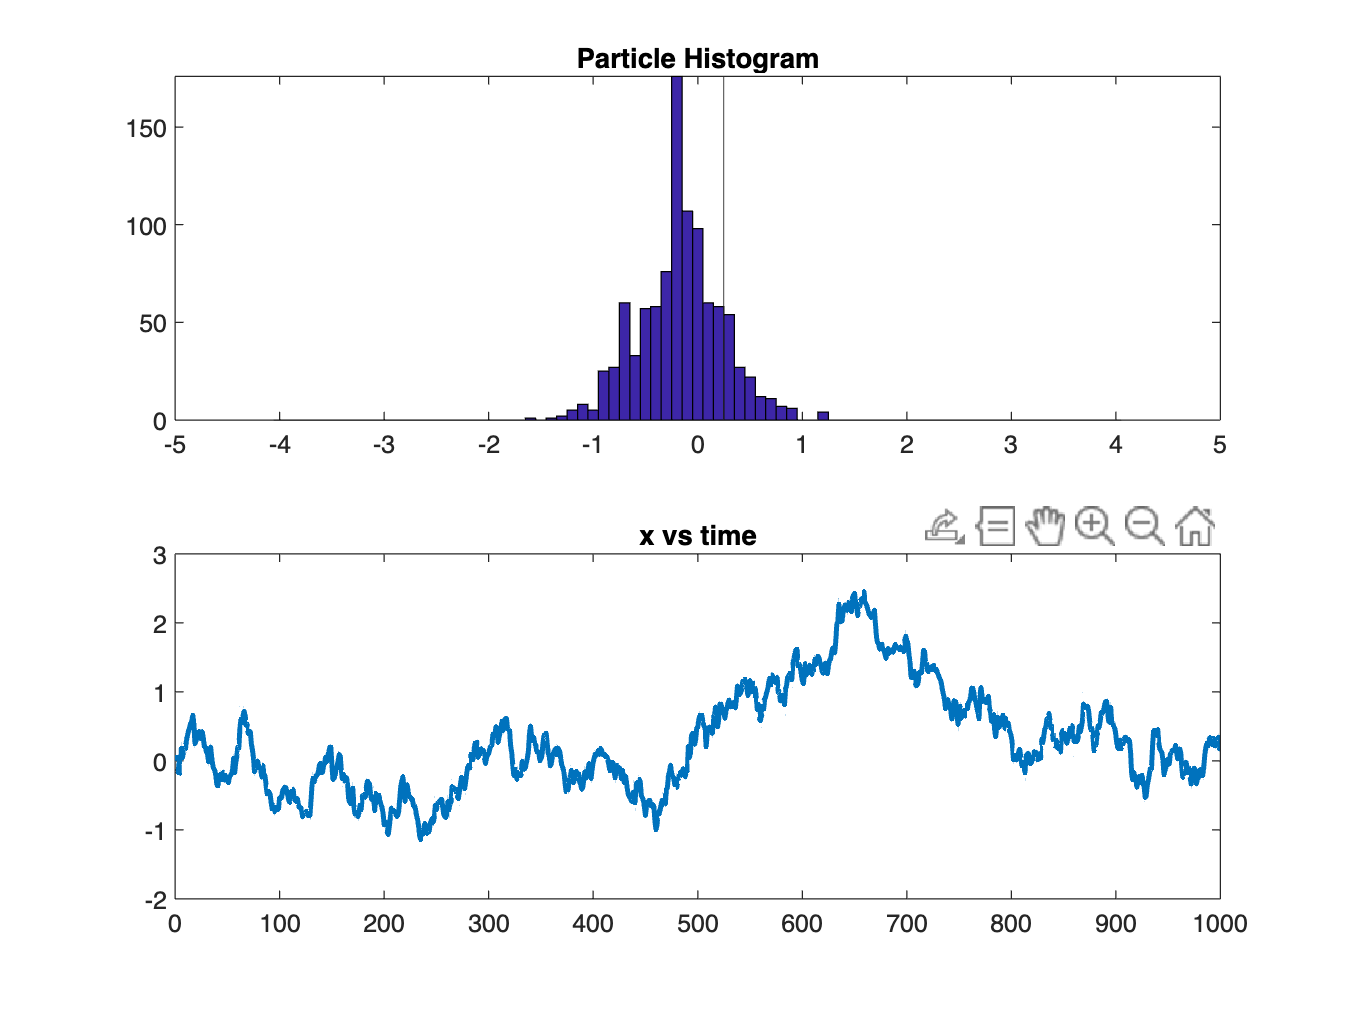

%% Particle Filter (Sequential Monte Carlo = SMC)
xs = [-4:.1:4]'; numSamp = 1000; xsmc = normrnd(0,1,1,numSamp);     % xsmc = estimated state for each sample

for k=2:N,
    xsmc = A*xsmc+Sigx*normrnd(0,1,1,numSamp);                      % Update each sample according to state model
    ws = normpdf(H*xsmc,y(k),Sigy); ws = ws./sum(ws);               % Compute weight for each sample based on likelihood of i^{th} data point 
    inds = datasample(1:numSamp,numSamp,'Weights',ws); xsmc = xsmc(:,inds); % Resample samples according to their weights
    meanSMC(k) = mean(xsmc)';                                    % State estimate is mean of samples
    sdSMC(k) = std(xsmc)';                                      % compute standard deviation of samples for confidence intervals

    subplot(211); hist(xsmc,xs); xline(x(k)); ylim([0 150]); title('Particle Histogram');
    subplot(212); plot(1:N,x); xline(k); title('x vs time');
    drawnow;
end;

This code should generate a movie similar to the previous section, but with $p\left(x_t |y_{1:t} \right)$ approximated by a histogram of the samples at each time point.

We can use the sample mean and sample standard deviation of the sample set at each time to compute a point estimate of the state and build confidence intervals

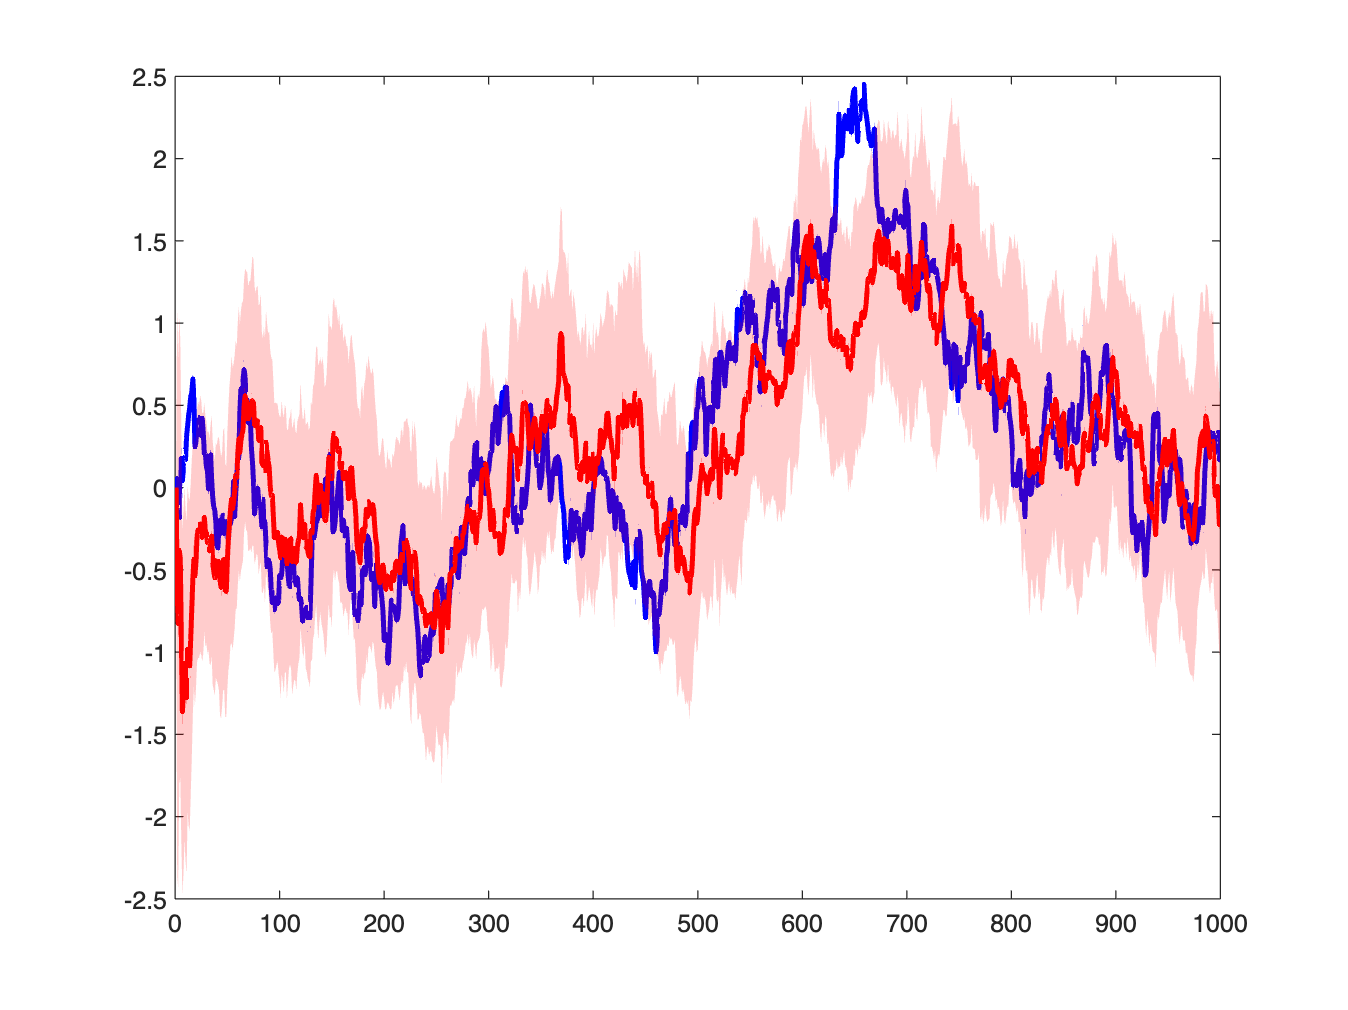

figure; plot(1:N,x,'b',1:N,meanSMC,'r'); U1=meanSMC+2*sdSMC; L1=meanSMC-2*sdSMC; hold on; fill([1:N N:-1:1], [U1 fliplr(L1)], 'r', 'FaceAlpha',0.2,'EdgeColor','none'); 

This plot shows the true values of x(t) in blue and the estimate of x(t) from the mean of the samples in red, with a shaded region representing 95% confidence intervals.  

In this example, the state model is linear in x(t-1) with Gaussian noise and the observation model is linear in x(t) with Gaussian noise. In this case, the integral above has an analytic solution given by the Kalman filter. The filter distribution turns out to be Gauusian at every time step, so the Kalman Filter only need to compute its mean and variance/covariance at each time step.   

%% Kalman Filter (Textbook version)
xK = zeros(1,N); WK = zeros(1,N);  WK(:,1) = 1;     % Allocate memory for xK (filter mean) and WK (filter variance)
tic; for i = 2:N,
    Wos = A*WK(:,i-1)*A'+Sigx*Sigx';                % One-step prediction variance
    Innovations = (y(:,i)-H*A*xK(:,i-1));
    S = H*Wos*H'+Sigy*Sigy';                        % Innovation covariance
    K = Wos*H'*inv(S);                              % Kalman Gain
    xK(:,i) = A*xK(:,i-1) + K*Innovations;          % Filter mean
    WK(:,i) = (1-K*H)*Wos;                          % Filter variance
end; toc

Elapsed time is 0.005120 seconds.


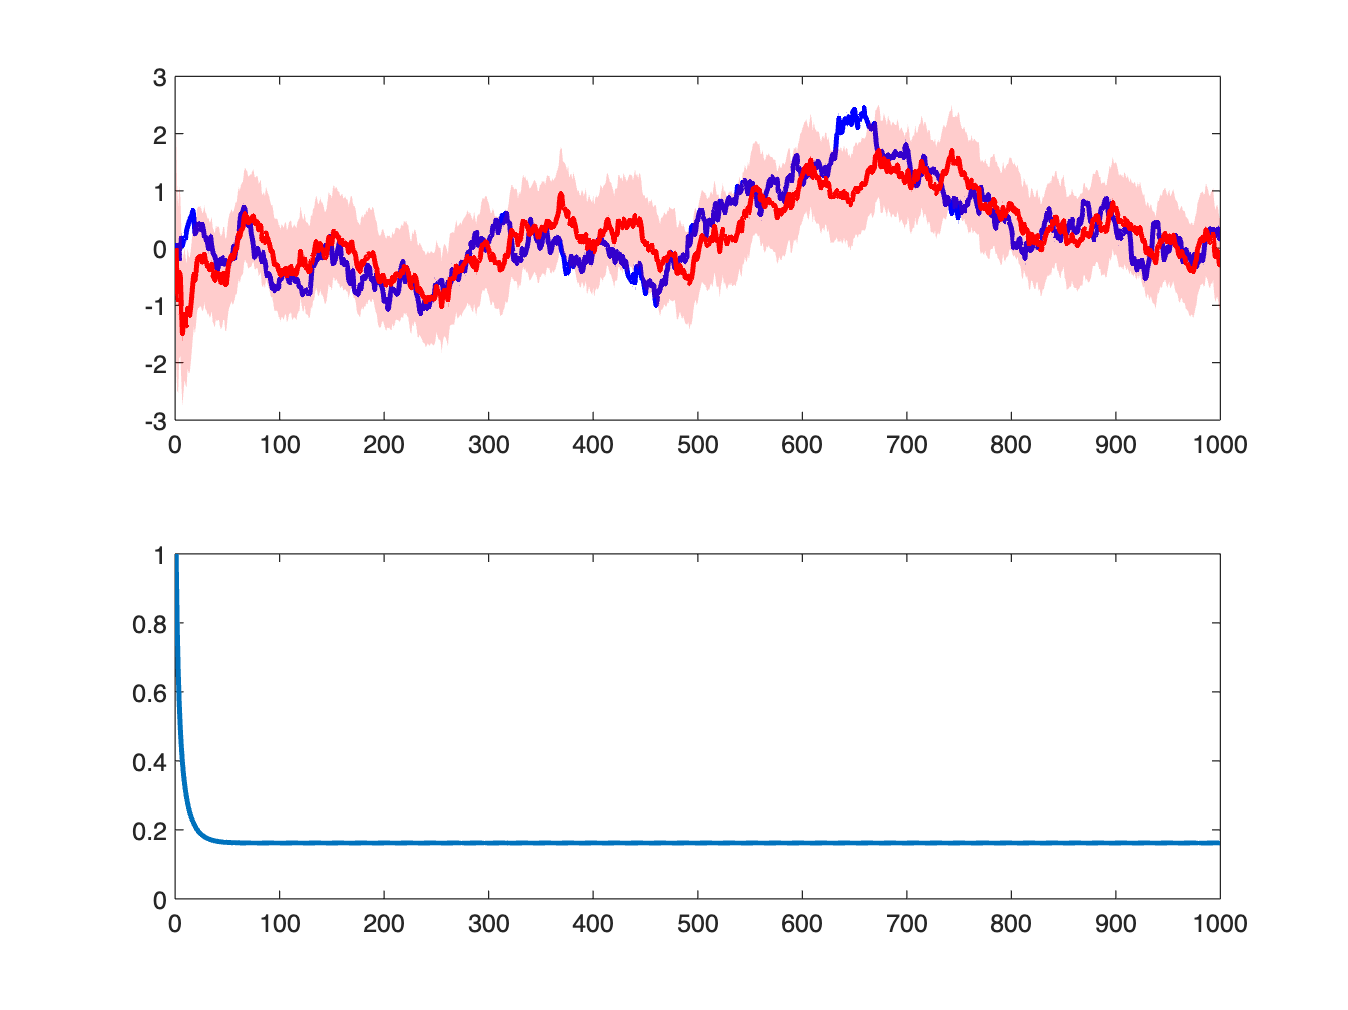


figure; subplot(211); plot(1:N,x,'b',1:N,xK,'r'); U1=xK+2*sqrt(WK); L1=xK-2*sqrt(WK); hold on; fill([1:N N:-1:1], [U1 fliplr(L1)], 'r', 'FaceAlpha',0.2,'EdgeColor','none'); 
subplot(212); plot(1:N,WK);

The top panel of this plot shows the true value of the state x(t) in blue and the Kalman Filter mean estimate of x(t) in red and a shaded region representing 95% confidence intervals. 

The bottom panel shows the variance of the filter distribution at each time step. The variance starts at its initial value and rapidly converges to a steady-state value. Note that in this case, the variance does not depend on the data. 

The Kalman Filter uses more code to acheive the same result as the numerical integration method for estimating the state process, but the computation is 1-2 orders of magnitude faster than numerical integration.

All of the procedures above solve the filter problem, which aims to estimate the state at time t given all of the data up to that time, without using any future data. Another problem is estimating the state at each time given all of the past and future data through some fixed interval. This is called the fixed-interval smoothing problem. If we assume there are N time steps, we would like to estimate the smoothing distribution $p\left(x_t |y_{1:N} \right)$. 

In class, we showed that this distribution can also be computed iteratively, this time stepping backward from the last time step, N, to the first time step.


$$p\left(x_t |y_{1:N} \right)=p\left(x_t |y_{1:t} \right)\int \frac{p\left(x_{t+1} |x_t \right)p\left(x_{t+1} |y_{1:N} \right)}{p\left(x_{t+1} |y_{1:t} \right)}{\textrm{dx}}_{t+1}$$


 The terms $p\left(x_t |y_{1:t} \right)$ and $p\left(x_{t+1} |y_{1:t} \right)$ come from the filter solution. As before, we can compute this integral numerically by multiplying the one-step transition matrix OST by the vector representing  $\frac{p\left(x_{t+1} |y_{1:N} \right)}{p\left(x_{t+1} |y_{1:t} \right)}$.

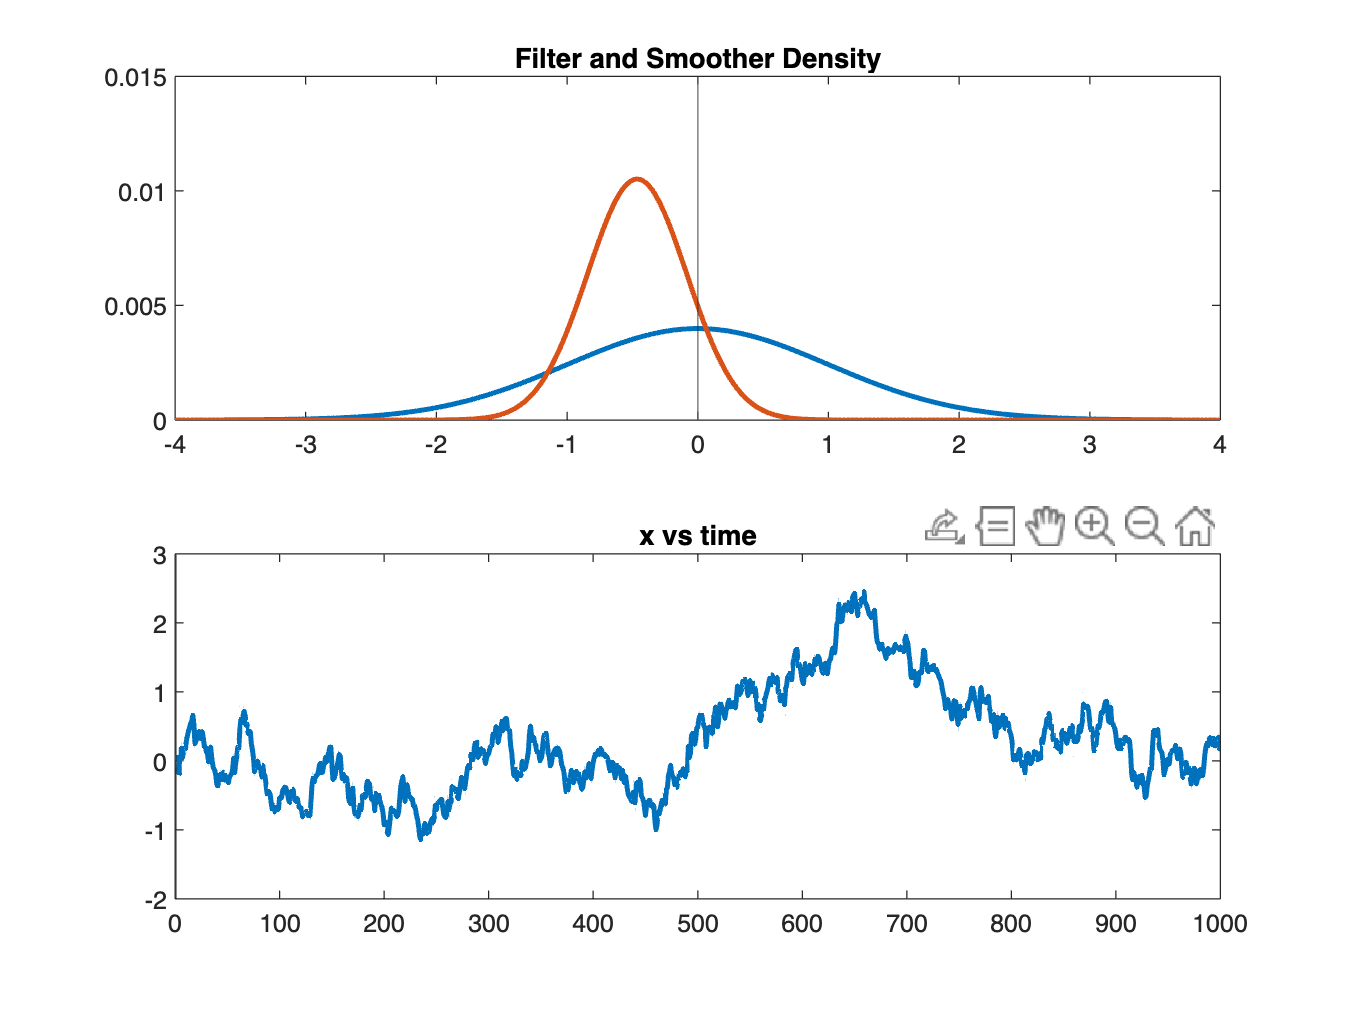

%% Smoother Solution (Numerical integration)
figure; xs = [-4:.01:4]'; xhatS = zeros(length(xs),N);      % Allocate memory for xhatS = p(x(t)|y(1:N))
xhatS(:,N) = xhatN(:,N);                            % Initialize xhatS(N) to filter solution at time N 
for i = N-1:-1:1,                              % Step backward from N down to 1

    post = xhatN(:,i).*(OST*(xhatS(:,i+1)./(OST*xhatN(:,i))));      % Compute unnormalized density p(x(t)|y(1:N)
    xhatS(:,i)=post./sum(post);                                     % Normalize to compute xhatS = p(x(t)|y(1:N))
    
    subplot(211); plot(xs,xhatN(:,i),xs,xhatS(:,i)); xline(x(i)); ylim([0 .015]); title('Filter and Smoother Density');
    subplot(212); plot(1:N,x); xline(i); title('x vs time');
    drawnow;
end;

This code should generate a movie that shows in the top panel both the smoother density, $p\left(x_t |y_{1:N} \right)$ in red and the filter density $p\left(x_t |y_{1:t} \right)$ in blue, at each time step. The vertical line show the actual value of x(t). The bottom plot shows the true values of x(t) through time with a vertical line that indicates the time step, t. The movie starts at the end time t=N, and steps backward in time. The smoother density is more concentrated and moves more smoothly than the filter density, reflecting the additional information available from the future as well as the past. 